The mean super class allows addition subtraction multiplication and division.

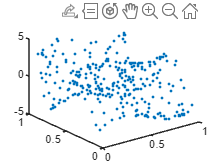

clear all
close all
clc

xx = lhsdesign(300,2);

a = means.const(3);

b = means.linear([0.1 0.2]);

c = means.linear([-0.1 -0.4]);

d = means.sine([1 2],[6 10],[0 4],[1 3]);

e = means.sine(1,5,4,3);

f = (c + a + d)*e;

K1 = d.eval(xx);
K2 = f.eval(xx);

figure
plot3(xx(:,1),xx(:,2),K1,'.')

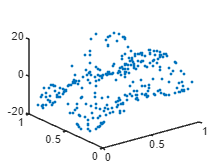


figure
plot3(xx(:,1),xx(:,2),K2,'.')

V = f.getHPs()

V =    -0.1000   -0.4000    3.0000    1.0000    3.0000    3.0000



f = f.setHPs(V+1);